# **UE1 USRP B210  Receiver **

## Set OFDM Frame Parameters

clear;

% The chosen set of OFDM parameters:
OFDMParams.FFTLength              = 512;   % FFT length
OFDMParams.CPLength               = 32;    % Cyclic prefix length
OFDMParams.NumSubcarriers         = 72;    % Number of sub-carriers in the band
OFDMParams.Subcarrierspacing      = 30e3;  % Sub-carrier spacing of 30 KHz
OFDMParams.PilotSubcarrierSpacing = 9;     % Pilot sub-carrier spacing
OFDMParams.channelBW              = 12e6;   % Bandwidth of the channel 3 MHz

% Data Parameters
dataParams.modOrder       = 64;   % Data modulation order
dataParams.coderate       = "3/4";   % Code rate
dataParams.numSymPerFrame = 30;   % Number of data symbols per frame
dataParams.numFrames      = 30;   % Number of frames to transmit
dataParams.enableScopes   = true;                    % Switch to enable or disable the visibility of scopes
dataParams.verbosity      = true;                    % Control to print the output diagnostics at each level of receiver processing
dataParams.printData      = true;                    % Control to print the output decoded data
dataParams.enableConst_measure = true;

## Initialize Receiver Parameters

radioDevice            = "B210";   % Choose radio device for reception
channelmapping         = 1;  % mutichannel or single channel selection
centerFrequency        = 2.5e9;  % Center Frequency
% centerFrequency        = 2.50288e9;
gain                   = 60;  % Set radio gain
gain                   = 40;
save_data              = false;
read_savedData         = false;

read_filename = 'saved_frameData_qam1024.bb';            % read saved received data from specific filename         
save_filename = 'saved_frameData_qam4096.bb';           % save receiving data to specific filename

[sysParam,txParam,transportBlk_bs1,transportBlk_bs2] = helperOFDMSetParamsSDR(OFDMParams,dataParams);
sampleRate                       = sysParam.scs*sysParam.FFTLen;                % Sample rate of signal
sysParam.enableTimescope = false;
sysParam.enableCFO = true;
sysParam.enableCPE = true;
sysParam.enableChest = true;
sysParam.enableHeaderCRCcheck = true;

if read_savedData
    bbr = comm.BasebandFileReader(read_filename, ...
    SamplesPerFrame=sysParam.txWaveformSize);
end
ofdmRx = helperGetRadioParams(sysParam,radioDevice,sampleRate,centerFrequency,gain,channelmapping);

Checking radio connections...


[radio,spectrumAnalyze,constDiag, timesink, constellation_measure] = helperGetRadioRxObj(ofdmRx);
% timesink = 1;
constDiag.ShowTrajectory = false;

## Execute Receiver Loop

#### Synchronization

#### Frequency Offset Estimation and Correction

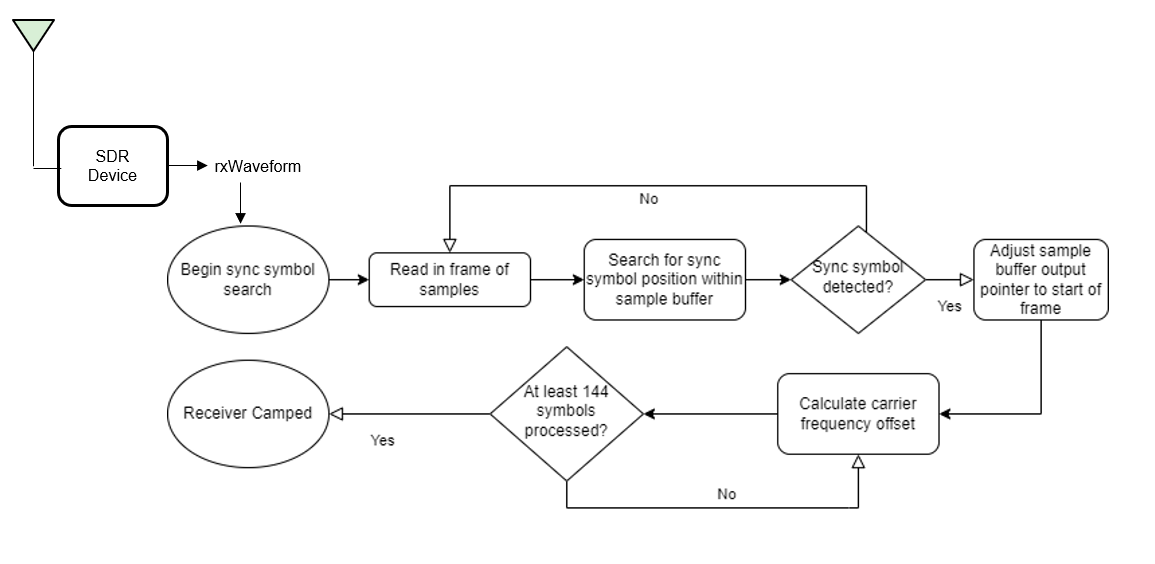

### Receiver Processing

#### Channel Estimation and Equalization

#### Header Decoding

#### Data Decoding

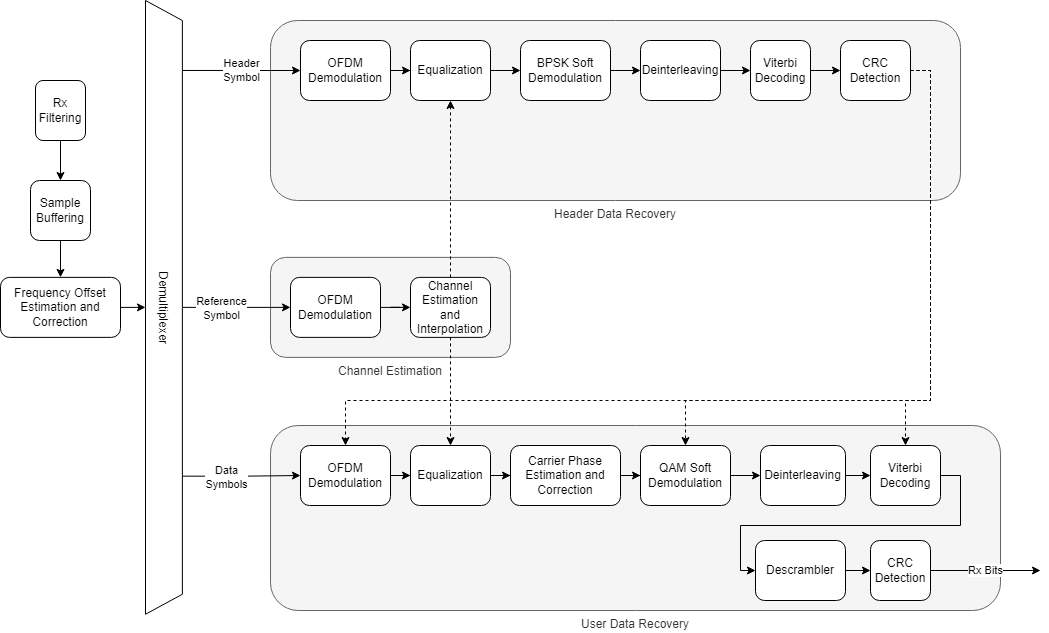

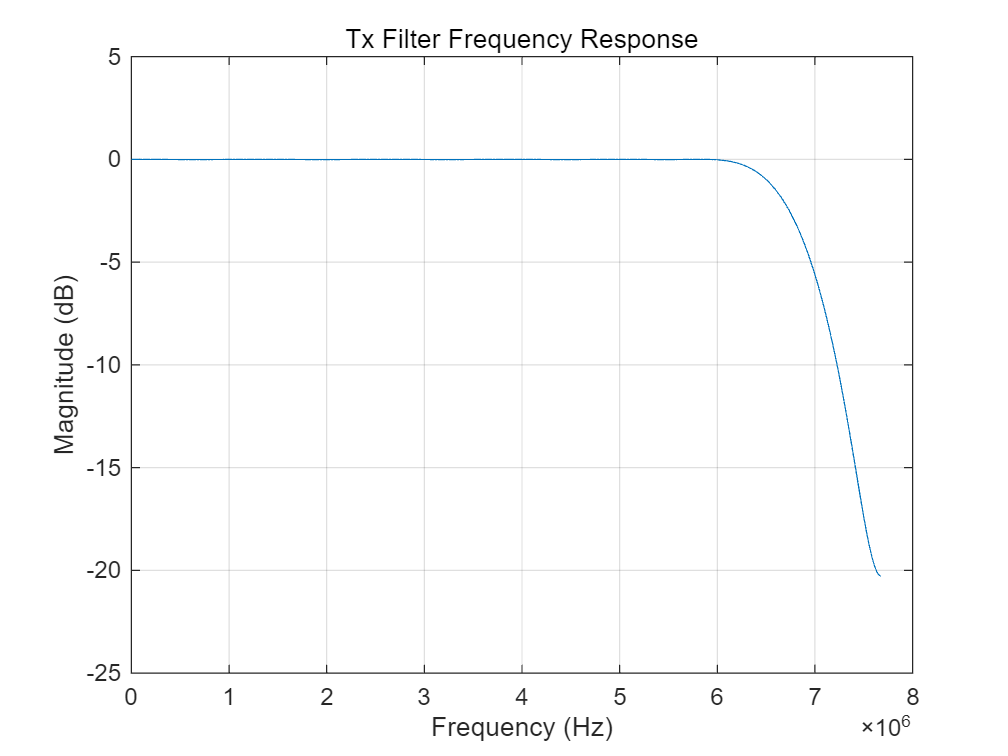

% Clear all the function data as they contain some persistent variables
clear helperOFDMRx helperOFDMRxFrontEnd helperOFDMRxSearch helperOFDMFrequencyOffset;
close all;


errorRate_bs1 = comm.ErrorRate();
errorRate_bs2 = comm.ErrorRate();
toverflow = 0; % Receiver overflow count
rxObj = helperOFDMRxInit(sysParam);


Sync symbol found.
Estimating carrier frequency offset ........
Receiver camped.
Detected and processing frame 8
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.890878e+03 Hz.
Correcting frequency offset across all samples


Header CRC failed


Received data in frame 8:                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                               

Detected and processing frame 9
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.849787e+03 Hz.
Correcting frequency offset across all samples


Header CRC failed


Received data in frame 9:                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                               

Detected and processing frame 10
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.024741e+03 Hz.
Correcting frequency offset across all samples


Header CRC failed


Received data in frame 10:                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                              

Detected and processing frame 11
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.225529e+03 Hz.
Correcting frequency offset across all samples


Header CRC failed


Received data in frame 11:                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                              

Detected and processing frame 12
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.040017e+03 Hz.
Correcting frequency offset across all samples


Header CRC failed


Received data in frame 12:                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                              

Detected and processing frame 13
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.753081e+03 Hz.
Correcting frequency offset across all samples


Header CRC failed


Received data in frame 13:                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                              

Detected and processing frame 14
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.926767e+03 Hz.
Correcting frequency offset across all samples


Header CRC failed


Received data in frame 14:                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                              

Detected and processing frame 15
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.105031e+03 Hz.
Correcting frequency offset across all samples


Header CRC failed


Received data in frame 15:                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                              

Detected and processing frame 16
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.933674e+03 Hz.
Correcting frequency offset across all samples


Header CRC failed


Received data in frame 16:                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                              

Detected and processing frame 17
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.669942e+03 Hz.
Correcting frequency offset across all samples


Header CRC failed


Received data in frame 17:                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                              

Detected and processing frame 18
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.622154e+03 Hz.
Correcting frequency offset across all samples


Header CRC failed


Received data in frame 18:                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                              

Detected and processing frame 19
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.327470e+03 Hz.
Correcting frequency offset across all samples


Header CRC failed


Received data in frame 19:                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                              

Detected and processing frame 20
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.391488e+03 Hz.
Correcting frequency offset across all samples


Header CRC failed


Received data in frame 20:                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                              

Detected and processing frame 21
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.410678e+03 Hz.
Correcting frequency offset across all samples


Header CRC failed


Received data in frame 21:                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                              

Detected and processing frame 22
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.932214e+03 Hz.
Correcting frequency offset across all samples


Header CRC failed


Received data in frame 22:                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                              

Detected and processing frame 23
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.132610e+03 Hz.
Correcting frequency offset across all samples


Header CRC failed


Received data in frame 23:                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                              

Detected and processing frame 24
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.973357e+03 Hz.
Correcting frequency offset across all samples


Header CRC failed


Received data in frame 24:                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                              

Detected and processing frame 25
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.861346e+03 Hz.
Correcting frequency offset across all samples


Header CRC failed


Received data in frame 25:                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                              

Detected and processing frame 26
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.625723e+03 Hz.
Correcting frequency offset across all samples


Header CRC failed


Received data in frame 26:                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                              

Detected and processing frame 27
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.654030e+03 Hz.
Correcting frequency offset across all samples


Header CRC failed


Received data in frame 27:                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                              

Detected and processing frame 28
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.793249e+03 Hz.
Correcting frequency offset across all samples


Header CRC failed


Received data in frame 28:                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                              

Detected and processing frame 29
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858324e+03 Hz.
Correcting frequency offset across all samples


Header CRC failed


Received data in frame 29:                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                              

Detected and processing frame 30
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.876410e+03 Hz.
Correcting frequency offset across all samples


Header CRC failed


Received data in frame 30:                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                              

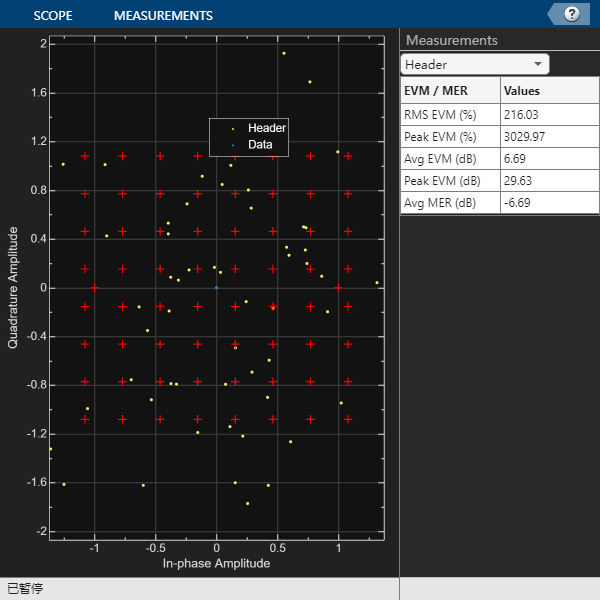

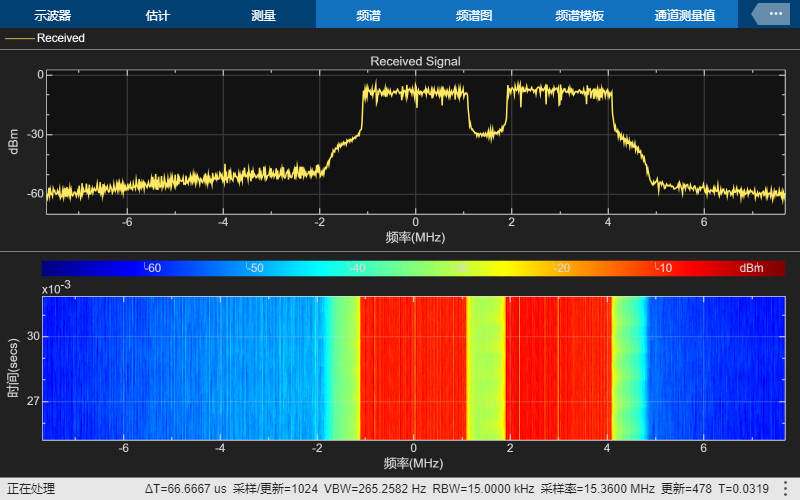

BER_bs1 = zeros(1,dataParams.numFrames);
BER_bs2 = zeros(1,dataParams.numFrames);
data_collec = [];
for frameNum = 1:dataParams.numFrames
    sysParam.frameNum = frameNum;
    if read_savedData
        rxWaveform = bbr();
        overflow = 0;
    else
        [rxWaveform, ~, overflow] = radio();
    end
    
    if save_data
        data_collec = [data_collec;rxWaveform];
    end
    toverflow = toverflow + overflow;

    % Run the receiver front-end only when there is no overflow
    if ~overflow
        rxIn = helperOFDMRxFrontEnd(rxWaveform,sysParam,rxObj);

        % Run the receiver processing
        [rxDataBits,isConnected,toff,rxDiagnostics] = helperOFDMRx(rxIn,sysParam,rxObj, timesink);
        sysParam.timingAdvance = toff;

        % Collect bit and frame error statistics
        if isConnected
            % Continuously update the bit error rate using the |comm.ErrorRate|
            % System object
            berVals_bs1 = errorRate_bs1(...
                transportBlk_bs1((1:sysParam.trBlkSize)).', ...
                rxDataBits);
            BER_bs1(frameNum) = berVals_bs1(1);

            berVals_bs2 = errorRate_bs2(...
                transportBlk_bs2((1:sysParam.trBlkSize)).', ...
                rxDataBits);
            BER_bs2(frameNum) = berVals_bs2(1);
            if dataParams.printData
                % As each character in the data is encoded by 7 bits, decode the received data upto last multiples of 7
                numBitsToDecode = length(rxDataBits) - mod(length(rxDataBits),7);
                recData = char(bit2int(reshape(rxDataBits(1:numBitsToDecode),7,[]),7));
                fprintf('Received data in frame %d: %s',frameNum,recData);
            end
        end

        if isConnected && dataParams.enableScopes
            constDiag(complex(rxDiagnostics.rxConstellationHeader(:)), ...
                complex(rxDiagnostics.rxConstellationData(:)));
        end

        rmsEVM_header = 0; 
        rmsEVM_data = 0; 
        merdb_header = 0;
        merdb_data = 0;

        if isConnected && dataParams.enableConst_measure
            rmsEVM_header = constellation_measure.evm_header(complex(rxDiagnostics.rxConstellationHeader(:))); 
            rmsEVM_data = constellation_measure.evm_data(complex(rxDiagnostics.rxConstellationData(:))); 
            merdb_header = constellation_measure.mer_header(complex(rxDiagnostics.rxConstellationHeader(:)));
            merdb_data = constellation_measure.mer_data(complex(rxDiagnostics.rxConstellationData(:)));
        end

        if dataParams.enableScopes
            spectrumAnalyze(rxWaveform);
        end
    end
end

% Display the mean BER value across all frames
fprintf(['Simulation complete!\n' ...
    'BS1 massage Average BER = %d \n' ...
    'BS2 massage Average BER = %d \n' ...
    '-------measurement-------\n' ...
    'Header rms EVM(%%): %.3f %% \n' ...
    'Data rms EVM(%%): %.3f %% \n' ...
    'Header MER(dB): %.3f dB \n' ...
    'Data MER(dB): %.3f dB'],mean(BER_bs1),mean(BER_bs2),rmsEVM_header, rmsEVM_data, merdb_header, merdb_data)

Simulation complete!
BS1 massage Average BER = 3.967089e-01 
BS2 massage Average BER = 3.669854e-01 
-------measurement-------
Header rms EVM(%): 216.034 % 
Data rms EVM(%): 100.000 % 
Header MER(dB): -6.690 dB 
Data MER(dB): -0.000 dB

% fprintf('-------measurement-------')
% fprintf('Header rms EVM(%%): %.3f %%', rmsEVM_header)
% fprintf('Data rms EVM(%%): %.3f %%', rmsEVM_data)
% fprintf('Header MER(dB): %.3f dB', merdb_header)
% fprintf('Data MER(dB): %.3f dB', merdb_data)
if save_data
    bbw = comm.BasebandFileWriter(save_filename,SampleRate=sampleRate,CenterFrequency=centerFrequency);
    bbw(data_collec);
    info(bbw)
    release(bbw)
end
if read_savedData
    release(bbr)
end
release(radio);